### PART B

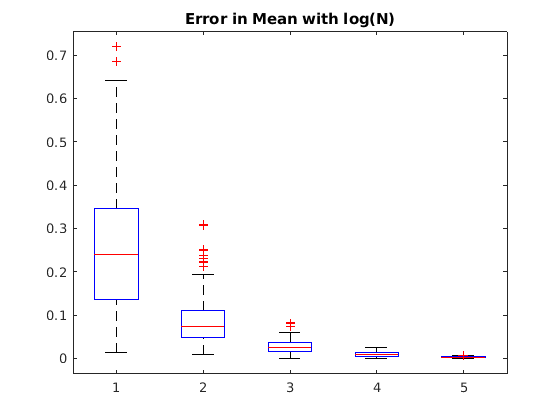

%given input
error_array_mean=[];
values=[10 100 1000 10000 100000];
for j=1:100
    error=[];
    for i=1:5
        N=values(i);
        mu=[1 2]';
        C=[1.6250, 1.9486*(-1); 1.9486*(-1), 3.8750];
        
        %calculating eigenvalues and eigenvectors of C
        [V,D] = eig(C);
        sqrt_diag=D^(1/2);
        
        %calculating matrix A
        A=V*sqrt_diag;
        
        %generating multivariate gaussian sampling
        G=randn(2,N);
        X=A*G + mu;
        
        %caclulating ML mean estimate
        S=sum(X,2);
        ML_mean_estimate=S./N;
        instance_error=norm(ML_mean_estimate-mu)/norm(mu);
        error=[error instance_error];
    end
    error_array_mean=[error_array_mean ; error];
end
boxplot(error_array_mean)
title('Error in Mean with log(N)')
saveas(gcf,sprintf('error_mean_2.png'));

### PART C

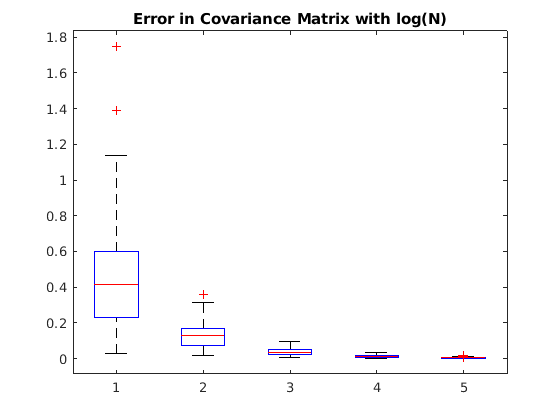

%given input
error_array_C=[];
values=[10 100 1000 10000 100000];
for j=1:100
    error=[];
    for i=1:5
        N=values(i);
        mu=[1 2]';
        C=[1.6250, 1.9486*(-1); 1.9486*(-1), 3.8750];
        
        %calculating eigenvalues and eigenvectors of C
        [V,D] = eig(C);
        sqrt_diag=D^(1/2);
        
        %calculating matrix A
        A=V*sqrt_diag;
        
        %generating multivariate gaussian sampling
        G=randn(2,N);
        X=A*G + mu;
        
        %caclulating ML covariance estimate
        Xt=X';
        St=sum(Xt);
        S=St';
        ML_mean_estimate=S./N;
        shift= X-mu;
        s=shift*shift';
        ML_covariance_estimate=s./N;
        instance_error=norm(ML_covariance_estimate-C,'fro')/norm(C,'fro');
        error=[error instance_error];
    end
    error_array_C=[error_array_C ; error];
end
boxplot(error_array_C)
title('Error in Covariance Matrix with log(N)')
saveas(gcf,sprintf('error_cov_2.png'));

### PART D

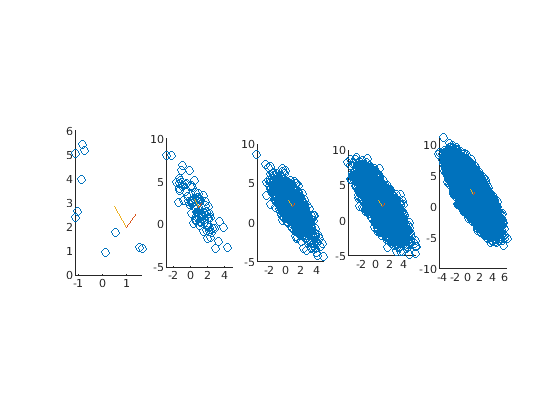

values=[10 100 1000 10000 100000];
for i=1:5
        N=values(i);
        mu=[1 2]';
        C=[1.6250, 1.9486*(-1); 1.9486*(-1), 3.8750];
        
        %calculating eigenvalues and eigenvectors of C
        [V,D] = eig(C);
        sqrt_diag=D^(1/2);
        
        %calculating matrix A
        A=V*sqrt_diag;
        
        %generating multivariate gaussian sampling
        G=randn(2,N);
        X=A*G + mu;

        %plotting
        x=X(1,:);
        y=X(2,:);
        subplot(1,5,i)
        scatter(x,y)
        hold on
        plot([1 1.432],[2 2.58139])
        plot([0.5 1],[2.8686 2])
        hold off
        daspect([1 1 1])
end
saveas(gcf,sprintf('trials_with_line2.png'));